# Identificazione dei parametri dinamici - calcolo del rango e dei parametri base

Modello del robot


$$\tau=\tau_{dyn}(q,\dot{q},\ddot{q})+ \tau_f(\dot{q}) =  \Phi(q,\dot{q},\ddot{q}) p$$


dove


$$\tau_{dyn}(q,\dot{q},\ddot{q})=B(q)\ddot{q} + C(q,\dot{q}) + G(q) = \Phi_{dyn}(q,\dot{q},\ddot{q}) p_{dyn}$$



$$\tau_f(\dot{q})=h_v \dot{q} + h_C  sign({\dot{q})} = \Phi_{f}(\dot{q}(t)) p_{f}$$


e quindi si può scrivere


$$\tau =  \Phi(q,\dot{q},\ddot{q}) p =  \Phi_{dyn}(q,\dot{q},\ddot{q}) p_{dyn}+\Phi_{f}(\dot{q}(t)) p_{f}$$


con 

$\Phi(q(t),\dot{q}(t),\ddot{q}(t))=\left[ 
 \begin{array}{cc}
\Phi_{dyn}(q(t),\dot{q}(t),\ddot{q}(t)) &  \Phi_{f}(\dot{q}(t)) 
 \end{array}
\right]$ e $p=
\left[ 
 \begin{array}{c}
p_{dyn}\\
p_{f}
 \end{array}
\right]$

pin=py.importlib.import_module('pinocchio'); % py. chiama il comando python % pinocchio calcola il regressore
numpy=py.importlib.import_module('numpy');

model_name="gantry_portal_sea_soft"; % nome del robot usato
model = py.pinocchio.buildModelFromMJCF('../labauto_assignment_1_2026'+ model_name+"/rigid_model.xml"); % descrizione della struttura del robot

Warning - Only texture with files are supported
Warning - Only texture with files are supported
Warning - Only texture with files are supported
Warning - Only texture with files are supported


model_data = model.createData(); % valori di posizione, velocità e accelerazioni del robot % configurazione del robot (posizione attuale)
dof=double(model.nq); % numero dei giunti: gradi di liberta (NB double = cast, perchè model.nq è un int pthon e non un int matlab)


Creo una matrice del regressore ottenuta con dati causali

% ogni link ha una massa, un centro e un'inerzia ma non tutti contribuiscono a
% generare una coppia, quindi devo capire quali mi servono, per farlo:
% lo faccio per capire quali colonne sono indipendenti e quali nulle (che
% scarterò)
A=[];
for idx=1:10000
    q=randn(dof,1);
    q_numpy=py.numpy.array(q);

    v=randn(dof,1);
    v_numpy=py.numpy.array(v);

    a=randn(dof,1);
    a_numpy=py.numpy.array(a);
    Phi_dynamic=double(py.pinocchio.computeJointTorqueRegressor(model,model_data,q_numpy,v_numpy,a_numpy));
    Phi_friction=[diag(v) diag(sign(v))];
    Phi=[Phi_dynamic,Phi_friction];
    A=[A;Phi];
end

calcolo il rango e la decomposizione QR della trasposta

b=rank(A);
[Q,R]=qr(A');

Traspongo R

Rt=R';

le prime $b$ righe sono diverse da zero infatti

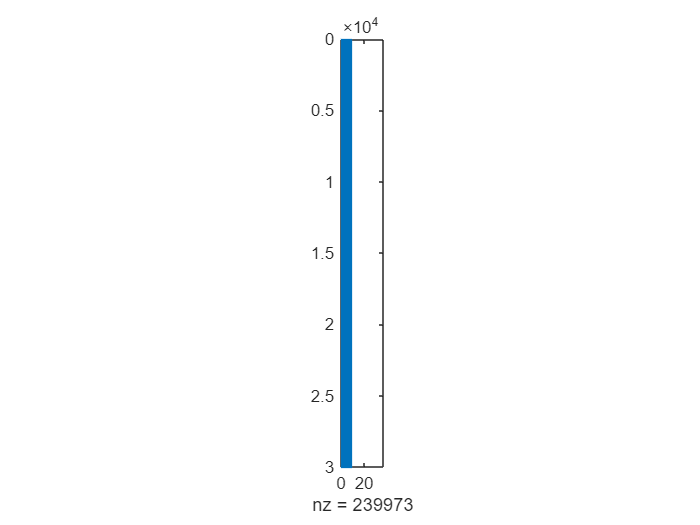

spy(abs(R')>1e-10) % colonne bianche sono nulle, colonne blu sono indipendenti

Ab=Rt(:,1:b);

La matrice $Q^{-1}=Q^T$ è la matrice di cambiamento di variabile desiderata, la rinomino $T$.

T=Q'; 
save('../labauto_assignment_1_2026'+ model_name+"/regressorT.mat",'T','b');